clear all;
Path = './data/matlabPIVinfo/'

Path = './data/matlabPIVinfo/'

File = './data/matlabPIVinfo/*.mat';
FileName = dir(File); FileName = extractfield(FileName, 'name');

i = 3

i = 3

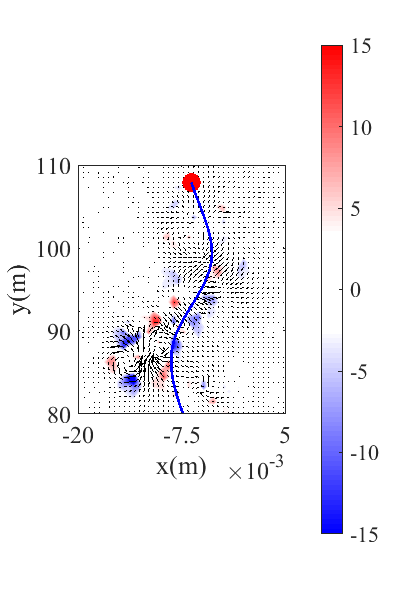

Name = FileName{i};
SaveName = split(Name, '.'); SaveName = SaveName{1};
load([Path, Name]);
index = find(X == X(1));
reshapeSize = index(2) - 1;
X = X - max(X);
Y = Y - (max(Y) + min(Y))/2;

X = X/1000; Y = Y/1000;
L = length(X);
X = reshape(X, [reshapeSize, L/reshapeSize])';
Y = reshape(Y, [reshapeSize, L/reshapeSize])';
[L, t] = size(Uall);
Uall = reshape(Uall, [reshapeSize, L/reshapeSize, t]);
Vall = reshape(Vall, [reshapeSize, L/reshapeSize, t]);
Uall = permute(Uall, [2,1,3]);
Vall = permute(Vall, [2,1,3]);
load(['./data/matlabPTVinfo/', SaveName,'.mat']);
trajX = -traj3D(:,1)/1000;
trajZ = -traj3D(:,3)/1000 - 80/800 * 60 /1000;
trajY = traj3D(:,2)/1000;

figure(1);
clf;
k = 99;
step = 1;
U = Uall(:,:,k); V = Vall(:,:,k);
%quiver(Y,X,V,U,5, 'k');
U = imgaussfilt(U,'FilterSize',3);
V = imgaussfilt(V,'FilterSize',3);

U1 = U(1:step:end,1:step:end);
V1 = V(1:step:end,1:step:end);

X1 = X(1:step:end,1:step:end);
Y1 = Y(1:step:end,1:step:end);

dx = X(1,2) - X(1,1);
dy = Y(1,1) - Y(2,1);
[dUdx, dUdy] = gradient(U1,dx,dy);
[dVdx, dVdy] = gradient(V1,dx,dy);
for i=1:size(U,1)
    for j=1:size(U,2)
        Vel_tensor = [dUdx(i,j) dVdx(i,j);...
                      dUdy(i,j) dVdy(i,j)];
        d = eig(Vel_tensor);
        lambda(i,j) = abs(imag(d(2,1)));
    end
end
Vorticity = dVdx - dUdy;
Lambda = lambda.*(Vorticity./abs(Vorticity));

[C,h] = contourf(X1,Y1,Lambda,100,'LineColor','none');
load('redBlue.mat');
colormap(cm);
caxis([-15 15]);
cb = colorbar;
%set(cb,'position',[0.92,0.24,0.0575,0.558333333333334])

hold on;
quiver(X1,Y1,U1,V1,3,'k');
%         camroll(-90);
axis equal;
%plot circle 
hold on;
m = min([k, length(trajX)]);
Bubble = scatter(trajZ(m), trajX(m),200, 'o', 'MarkerFaceColor','r', 'MarkerEdgeColor','none');
hold on;
plot(trajZ(1:m), trajX(1:m),'b','LineWidth',2);
hold off;
%alpha(Bubble,abs(trajY(m))/max(abs(trajY))*0.7 + 0.3);






xlim([-0.11, -0.08]);
ylim([-0.02,0.005]);
set(gca,'XTick',[-0.11:0.01:-0.08]);
set(gca,'YTick',[-0.02, -0.0075, 0.005]);
camroll(-90); 
xticks = [0.08:0.01:0.11] * 1000;
xticks = num2cell(xticks);
xticks = string(xticks);
xticks = cellstr(xticks);
xticklabels(flip(xticks));





ylabel('x(m)');
xlabel('y(m)');
set(gca,'yAxisLocation','right');
set(gca, 'FontName', 'Times');
%title(['t = ', num2str(k)]);
set(gcf,'Position',[0 0 400 600]);
set(gcf,'color','w');
set(gca,'FontSize',18);

%savefig(gcf, 'KH.fig');


**load trajectory**

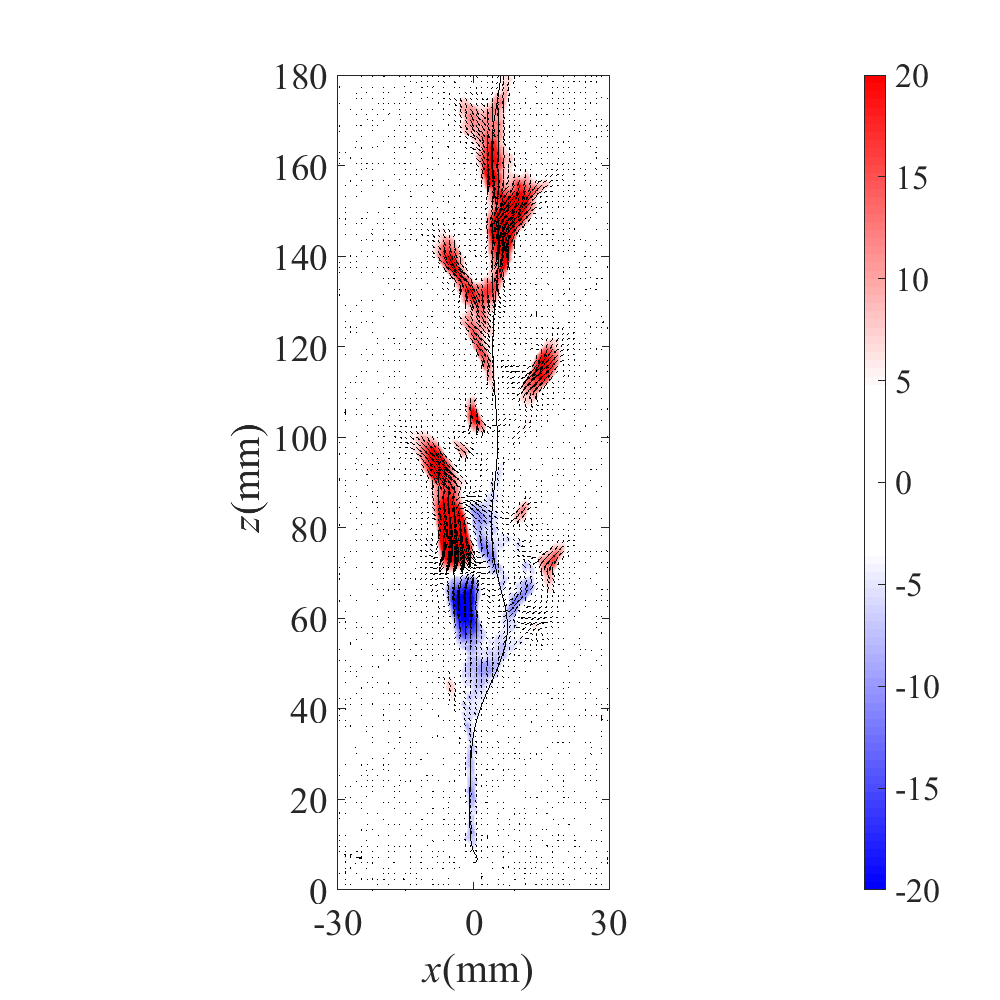

cbh =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-0.0200 0.0200]
    FontSize: 25.2000
    Position: [0.8651 0.1100 0.0213 0.8150]
       Units: 'normalized'

  Show all properties


%FileName = FileName.name;

for i = 2:2
    clear eVec eValue;
    Name = FileName{i};
    SaveName = split(Name, '.'); SaveName = SaveName{1};
    load([Path, Name]);
    index = find(X == X(1));
    reshapeSize = index(2) - 1;
    X = X - max(X);
    Y = Y - (max(Y) + min(Y))/2;
    
    X = X/1000; Y = Y/1000;
    L = length(X);
    X = reshape(X, [reshapeSize, L/reshapeSize])';
    Y = reshape(Y, [reshapeSize, L/reshapeSize])';
    [L, t] = size(Uall);
    Uall = reshape(Uall, [reshapeSize, L/reshapeSize, t]);
    Vall = reshape(Vall, [reshapeSize, L/reshapeSize, t]);
    Uall = permute(Uall, [2,1,3]);
    Vall = permute(Vall, [2,1,3]);

**load trajectory**

    
    load(['./data/matlabPTVinfo/', SaveName,'.mat']);
    trajX = -traj3D(:,1)/1000;
    trajZ = -traj3D(:,3)/1000 - 80/800 * 60 /1000;
    trajY = traj3D(:,2)/1000;
    

**POD**

    
    Up = Uall - mean(Uall, 3); % calculate fluctuation 
    Vp = Vall - mean(Vall, 3);
    [m,n,t] = size(Uall);
    UpPOD = reshape(Up, [m * n, t]);
    VpPOD = reshape(Vp, [m * n, t]);
    UpAll = [UpPOD(:,1:t); VpPOD(:,1:t)];
    R= UpAll'*UpAll; % Autocovariance matrix
    [eV,D]=eig(R); % solve: eV is eigenvectors, D is eigenvalues in diagonal matrix
    [L,I]=sort(diag(D),'descend'); % sort eigenvalues in decending order - I is sorted index vector
    for j=1:length(D)
        eValue(j)=L(j); % Eigenvalues sorted in descending order
        eVec(:,j)=eV(:,I(j)); % Eigenvectors sorted in the same order
    end
    eValue(length(eValue))=0; % last eigenvalue should be zero
    menergy=eValue/sum(eValue); % relative energy associated with mode m
    
%     figure();
%     bar(menergy(:,1:10)); % plot first 10 mode
%     menergy_cum = cumsum(menergy); 
%     figure();
%     plot(menergy_cum);
%     figure();
%     plot(log10(eValue),'.')
%     ylabel('log_{10}(\sigma)')
%     hold on
    k = 100; 
%     plot(1:length(eValue),ones(size(eValue))*log10(eValue(k)),'r')
    for j=1:k  %should use all t images but to save time just find the first k that are of our interest here
        tmp=UpAll*eVec(:,j); % find mode, tmp is the left sigular vectors
        %phi(:,i) = UPall*eVec(:,i)/(eValue(i).^(.5)); %we are deviding the singular value same as normalized by its own norm
        phi(:,j)=tmp/norm(tmp); % phi is the left singular vectors 
    end
    
    phi_restrict = phi(:,1:k);
    
    %Project a face onto this limited set 
    A = zeros(k,t); % the energy coefficient as a_i(t) for the i-th snapshot, here get the coefficient for each image 
    
    % find the coefficient a_i associate to each mode for a given image, using projection
    for j = 1:t
        A(:,j) = UpAll(:,j)'*phi_restrict; %use matrix multiplication to replace dot product, 
    end
    figure(6)
    clf;
    for j = 1:1% Plot first 8 mode
        %subplot(3,3,j);
        %colormap('jet');
        %colormap('jet')
        %[C,h] = contourf(reshape(phi(1:m*n,i),m,n)',500,'LineStyle','none');
        [C,h] = contourf(X,Y,reshape(phi_restrict(1:m*n,j),m,n),100,'LineColor','none');
        load('redBlue.mat');
        colormap(cm);
        
        hold on;
        Up = phi_restrict(1:m*n,j);
        Vp = phi_restrict(m*n+1:end,j);
        step = 2;
        
        Up = reshape(Up, [m ,n]);
        Vp = reshape(Vp, [m, n]);
        
        Up = Up(1:step:end,1:step:end);
        Vp = Vp(1:step:end,1:step:end);
        Xp = X(1:step:end,1:step:end);
        Yp = Y(1:step:end,1:step:end);
        quiver(Xp,Yp,Up,Vp,3,'k');
        
        caxis([-0.02 0.02]);
        hold on; 
        plot(trajZ, trajX, 'k');
        hold off;
        xlim([-0.18, 0]);
        ylim([-0.03,0.03]);
        set(gca,'XTick',[-0.18:0.02:0]);
        camroll(-90); 
        xticks = [0:0.02:0.18] * 1000;
        xticks = num2cell(xticks);
        xticks = string(xticks);
        xticks = cellstr(xticks);
        xticklabels(flip(xticks));
        
        %caxis([-0.035 0.035]);
        ylabel('{\it x}(mm)');
        xlabel('{\it z}(mm)');
        set(gca,'yAxisLocation','right');
%         title(['mode = ', num2str(j)]);
        cbh = colorbar;
        %xlim([-0.03,0.03])
        axis equal;
        set(gca, 'YDir','reverse')
        ylim([-0.03 0.03]);
        yticks([-0.03, 0, 0.03]);
        yticklabels({'30', '0', '-30'});
        
        %title(SaveName);
        %ylim([0,0.2])
        set(gcf,'Position',[0 0 1000 1000]);
        set(gca, 'FontName', 'Times');
        set(gca,'FontSize',28);
        set(gcf,'color','w');
        
        cbh.TickLabels = num2cell([-0.02:0.005:0.02] * 1000)
%         saveas(gcf, [ SaveName,'.png']);
        %savefig(gcf, [ SaveName,'.fig']);
    end
%     figure()
%     for i = 1:8
%         subplot(3,3,i);
%         plot(A(:,i));
%         ylim([-2,2]);
%     end
end
    

**Test for quiver**

%     step = 1;
%     clear F;
%     for k = 1:t
%         figure(1);
%         clf;
%         U = Uall(:,:,k); V = Vall(:,:,k);
%         %quiver(Y,X,V,U,5, 'k');
%         U = imgaussfilt(U,'FilterSize',3);
%         V = imgaussfilt(V,'FilterSize',3);
%         
%         U1 = U(1:step:end,1:step:end);
%         V1 = V(1:step:end,1:step:end);
%         
%         X1 = X(1:step:end,1:step:end);
%         Y1 = Y(1:step:end,1:step:end);
%         quiver(X1,Y1,U1,V1,3);
% %         camroll(-90);
%         axis equal;
%         %plot circle 
%         hold on;
%         m = min([k, length(trajX)]);
%         Bubble = scatter(trajZ(m), trajX(m),50, 'o', 'MarkerFaceColor','r', 'MarkerEdgeColor','none');
%         hold on;
%         plot(trajZ(1:m), trajX(1:m),'k');
%         hold off;
%         alpha(Bubble,abs(trajY(m))/max(abs(trajY))*0.7 + 0.3);
%         
%         xlim([-0.2, 0]);
%         ylim([-0.03,0.03]);
%         set(gca,'XTick',[-0.2:0.02:0]);
%         camroll(-90); 
%         xticks = [0:0.02:0.2];
%         xticks = num2cell(xticks);
%         xticks = string(xticks);
%         xticks = cellstr(xticks);
%         xticklabels(flip(xticks));
% 
%         ylabel('x(m)');
%         xlabel('y(m)');
%         set(gca,'yAxisLocation','right');
%         title(['t = ', num2str(k)]);
%         set(gcf,'Position',[0 0 400 1080]);
%         F(k) = getframe(gcf);
%     end
%     myVideo = VideoWriter([SaveName, 'Quiver.avi']); %open video file
%     myVideo.FrameRate = 10;  %can adjust this, 5 - 10 works well for me
%     open(myVideo)
%     for pp=1:length(F)
%         % convert the image to a frame
%         frame = F(pp);    
%         writeVideo(myVideo, frame);
%     end
%     close(myVideo);       
%    

**Computer the vorticity in CPU**

%     vor = [];
%     tic;
%     for s=1:t
%         U = Uall(:,:,s); V = Vall(:,:,s);
%         U = imgaussfilt(U,'FilterSize',3);
%         V = imgaussfilt(V,'FilterSize',3);
%         vor(:,:,s)=curl(X,Y,U,V);
%     end
%     toc;
%     clear F;
%     for k = 1:t
%         figure(2);
%         clf;
%         [C,h] = contourf(X,Y,vor(:,:,k),100,'LineColor','none');
%     %     colorMap = redblue(100);% if you first time use 
%         load('redBlue.mat');
%         colormap(cm);
%         axis equal;
%         colorMin = -35;
%         colorMax = 35;
%         caxis([colorMin colorMax]);
%         m = min([k, length(trajX)]);
%         hold on;
%         Bubble = scatter(trajZ(m), trajX(m),50, 'o', 'MarkerFaceColor',[0.9290 0.6940 0.1250], 'MarkerEdgeColor','none');
%         hold on;
%         plot(trajZ(1:m), trajX(1:m),'k');
%         hold off;
%         alpha(Bubble,abs(trajY(m))/max(abs(trajY))*0.7 + 0.3);
%         colorbar;
%         
%         xlim([-0.2, 0]);
%         ylim([-0.03,0.03]);
%         set(gca,'XTick',[-0.2:0.02:0]);
%         camroll(-90); 
%         xticks = [0:0.02:0.2];
%         xticks = num2cell(xticks);
%         xticks = string(xticks);
%         xticks = cellstr(xticks);
%         xticklabels(flip(xticks));
%       
%         ylabel('x(m)');
%         xlabel('y(m)');
%         set(gca,'yAxisLocation','right');
%         title(['t = ', num2str(k)]);
%         %title('vorticity(1/s)');
%         set(gcf,'Position',[0 0 400 1080]);
%         F(k) = getframe(gcf);
%     end
%   
%     myVideo = VideoWriter([SaveName, 'Vorticity.avi']); %open video file
%     myVideo.FrameRate = 10;  %can adjust this, 5 - 10 works well for me
%     open(myVideo)
%     for pp=1:length(F)
%         % convert the image to a frame
%         frame = F(pp);    
%         writeVideo(myVideo, frame);
%     end
%     close(myVideo);
%     i
% end


function c = redblue(m)
    if nargin < 1, m = size(get(gcf,'colormap'),1); end
    if (mod(m,2) == 0)
        % From [0 0 1] to [1 1 1], then [1 1 1] to [1 0 0];
        m1 = m*0.5;
        r = (0:m1-1)'/max(m1-1,1);
        g = r;
        r = [r; ones(m1,1)];
        g = [g; flipud(g)];
        b = flipud(r);
    else
        % From [0 0 1] to [1 1 1] to [1 0 0];
        m1 = floor(m*0.5);
        r = (0:m1-1)'/max(m1,1);
        g = r;
        r = [r; ones(m1+1,1)];
        g = [g; 1; flipud(g)];
        b = flipud(r);
    end
    c = [r g b]; 
end